clc; clearvars;

addpath(genpath("C:\Users\tely1\OneDrive\Matlab Onedrive\O3_Lidar\proc_functions"))
dataPath = "C:\Users\tely1\OneDrive\Desktop\EEJ9903\O3_DIAL_ML\signal_data\20251027";

data_format     = "bin";
prefix = "ol";

[scaled_data,times,configs] = read_lidar_datafiles(dataPath,data_format,prefix);
scaled_data = scaled_data(1:8000,:,1:2,:);

num_bins = size(scaled_data,1);
num_files = size(scaled_data,2);

files = 1:50;

data_an = scaled_data(:,files,1,1);
data_pc = scaled_data(:,files,1,2);

num_prof = size(data_an,2);

[~,gate_bin] = max(data_an,[],1);

for i = 1:num_prof
    data_an(1:gate_bin(i)-1,i) = NaN;
    data_pc(1:gate_bin(i)-1,i) = NaN;
end

deltaC = 1;
Cmin = 5;   % MHz
Cmax = 60;

id_valid = data_pc >= Cmin & data_pc <= Cmax;
[row,col] = ind2sub(size(data_an), find(id_valid));

C = Cmin:deltaC:Cmax;
N = length(C)-1;

Tau = (-1:0.01:6) .* 1e-9;
num_trials = length(Tau);

J = NaN(1,num_trials);
for trial = 1:num_trials
    tau_temp = Tau(trial);

    ck = NaN(1,N);
    ak = NaN(1,N);
    delta_ak = NaN(1,N);

    for i = 1:N
        Cmin_temp = C(i);
        Cmax_temp = C(i+1);
        id_valid_temp = data_pc >= Cmin_temp & data_pc <= Cmax_temp;
    
        ck(i) = median(data_pc(id_valid_temp)) .* 1e6;
        ak(i) = median(data_an(id_valid_temp));
        delta_ak(i) = std(data_an(id_valid_temp));
    end
    ck_prime = ck ./ (1 - tau_temp .* ck);

    mdl = fitlm(ck_prime,ak).Coefficients;
    ak_hat = ck_prime .* mdl.Estimate(2) + mdl.Estimate(1);

    J(trial) = (1/N) * sum((ak - ak_hat).^2 ./ (delta_ak.^2));
end

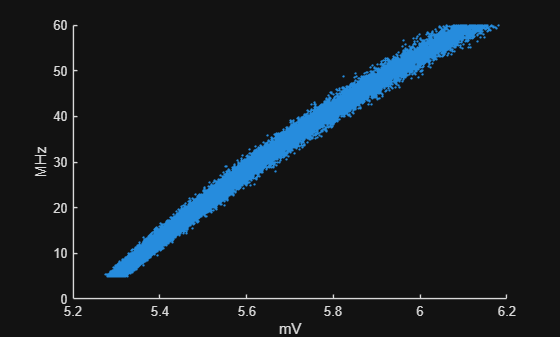

figure;
scatter(data_an(id_valid),data_pc(id_valid),1)
xlabel('mV')
ylabel('MHz')

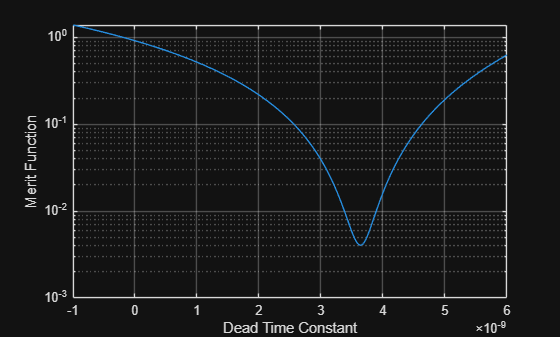

figure;
semilogy(Tau,J)
xlabel('Dead Time Constant')
ylabel('Merit Function')
grid on